## Project

Introduction

## 1. Data Load

- dt: the time interval

- K: max iterations

- N: Number of Agents (7)

- M: Number of Edges (12)

- Z: Actual positions of each agent (2D position)

- Z*: Target positions of each agent

- L: Edge weights ($l_{ij} $: the weight of the edge between positions of the i-th and j-th agent)

load("data.mat");

## 2. Initialization

L;
% for i=1:7
%     for j=1:7
%        if i ~= j
%           L(i,j) = abs(L(i,j));
%        end
%     end
% end
z_matrix = zeros(7, 2, K); % matrix of positions of all agents
z_matrix(:, :, 1) = z;     % initialize the 1-st position
k = 1; % current iteration
% u_matrix = zeros(7, 2, K) % input matrix

## 3. Loop

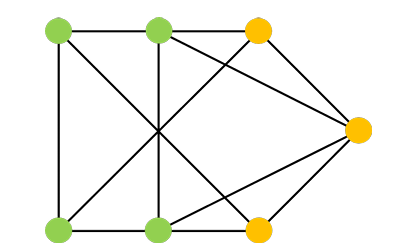

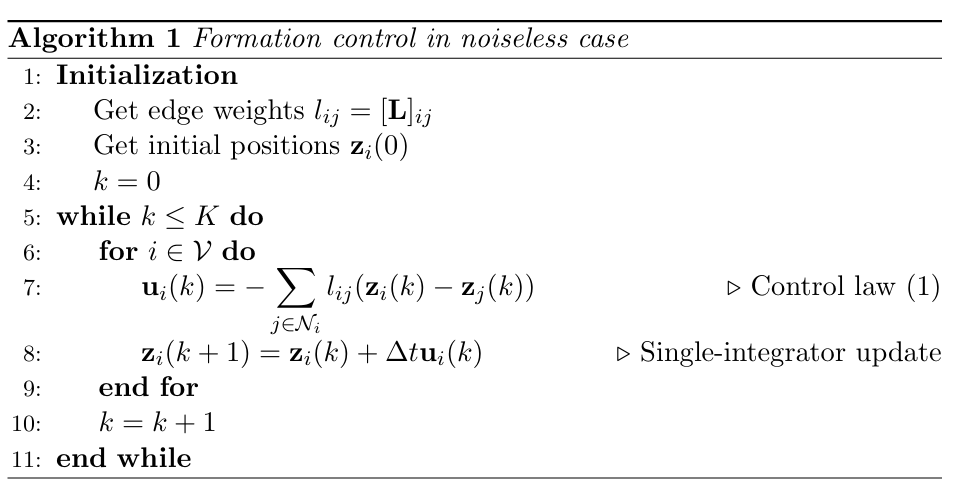

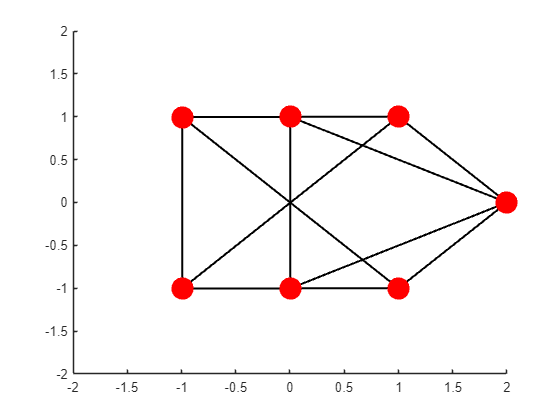

dt = 0.05;
K = 5000;
while k<=K
    for i = 1:N
 
        % 对k时刻的第ui进行计算 (ui(k))
        u_i_k = zeros(1, 2);
        z_i_k = z_matrix(i, :, k);

        for j = 1:N % 遍历L(i, j), 计算ui(k)
            u_i_k = u_i_k + L(i, j) * (z_matrix(i, :, k) - z_matrix(j, :, k));
        end
        if i == 1|| i==2 || i==3
            u_i_k = 0;
        end
        % 计算zi(k+1) = zi(k) + dt*ui(k)
        z_i_k_new = z_i_k + dt * u_i_k;
        z_matrix(i, :, k+1) = z_i_k_new;   % 赋值给z_matrix
    end
    k = k + 1;
    
end
error = compute_error(z_matrix, z_star, K);        % 计算误差
plot_formation(z_matrix(:, :, K));

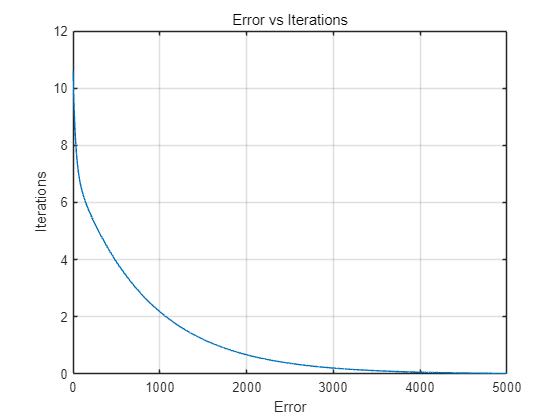

x_state = 1:K;
figure(2);
plot(x_state, error); 
xlabel("Error");
ylabel("Iterations");
title("Error vs Iterations");
grid on;

### 4. Add Noise

根据R施加噪声，总的来说会有收敛趋势，但是最后没办法收敛到理想位置

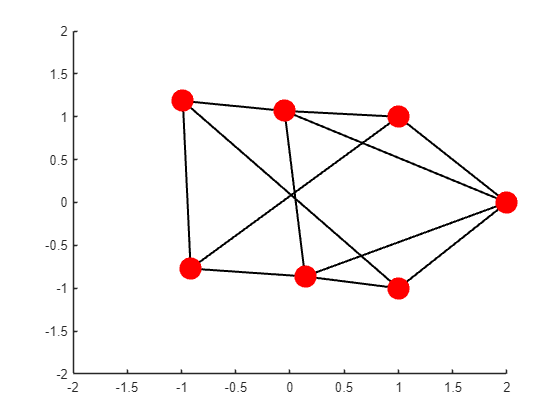

z_matrix2 = zeros(7, 2, K);
z_matrix2(:, :, 1) = z;
k = 1;
observations_m = zeros(12, 2, K);           % 用于保留观测值，因为一共只有12条边非0，所以只需要12个向量
while k<=K
    state_num = 0;
    for i = 1:N
        
        % 对k时刻的第ui进行计算 (ui(k))
        u_i_k = zeros(1, 2);
        z_i_k = z_matrix2(i, :, k);
        
        for j = 1:N % 遍历L(i, j), 计算ui(k)
            x_state = z_matrix2(i, :, k) - z_matrix2(j, :, k) + mvnrnd([0, 0], R);
            u_i_k = u_i_k + L(i, j) * x_state;
            %

            % x_matrix(i, j, :, k) = x; % 这样操作有问题，因为实际观测只需要看L不为0的
            % 状态量保留
            % 1. 只保留L不为0且非自环的观测值
            % 2. 只保留下三角矩阵中L不为0的值（因为L是对称矩阵）
            if(L(i, j)~=0 && i<j)
                state_num = state_num + 1;
                observations_m(state_num, :, k) = x_state;
            end
        end
        
        % 如果计算的是第i个智能体的输入，那么设为0，因为他们不会变化位置
        if i == 1|| i==2 || i==3
            u_i_k = 0;
        end

        % 计算zi(k+1) = zi(k) + dt*ui(k)
        z_i_k_new = z_i_k + dt * u_i_k;
        z_matrix2(i, :, k+1) = z_i_k_new;   % 赋值给z_matrix
    end
    k = k + 1;
    
end

error = compute_error(z_matrix2, z_star, K);        % 计算误差
x = 1:5000;
plot_formation(z_matrix2(:, :, K));

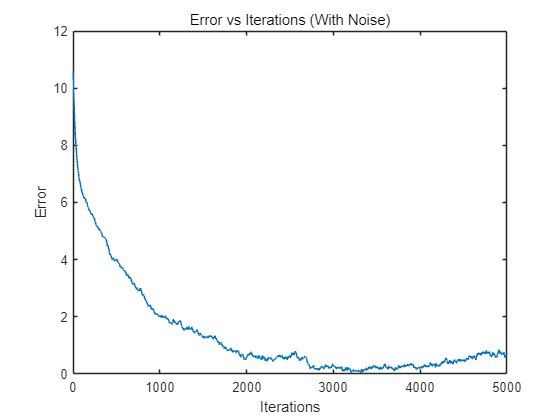

figure(3);
plot(x, error);
xlabel("Iterations");
ylabel("Error");
title("Error vs Iterations (With Noise)");

### 5. Estimator